clear; close all; clc; % initializes environment

# 固有値分解とグラフの回転

## 本章の目的

前章では，正射影ベクトルの長さの分散$S=\left(u,\mathit{Vu}\right)$を分散共分散行列$V$の固有値分解$V=\mathit{QD}Q^T$を用いて式変形して，$S=\left(u\prime ,\mathit{Du}\prime \right)$という式を導出しました（ただし，$u\prime =Q^T u$）．そして，$S=\left(u\prime ,\mathit{Du}\prime \right)$のグラフは$S=\left(u,\mathit{Vu}\right)$を回転させたグラフであることを解説しました．

本章では，この回転について詳しく見ていきます．ここでは，$u\prime =Q^T u$という関係が鍵となります．本章では，一般の行列による写像を解説し，$u\prime =Q^T u$というベクトルと行列の掛け算の幾何学的なイメージを解説していきます．その後，座標の回転と座標軸の回転について解説していきます．

## データの準備

### データの読み込み

引き続き，「米国３２９都市における生活満足度」のデータセットを用います．また，「健康」と「芸術」に関する指標を用いて，変数とする二変量データとして解説していきます．さらに，説明を簡単にするために，平均値が０，標準偏差が１になるように正規化しておきます．

load cities.mat;
scores_health_norm = normalize(ratings(:, 3)); % extracts scores on healt (the 3rd  column) and normalizes it
scores_arts_norm = normalize(ratings(:, 7)); % extracts scores on arts (the 7th column) and normalizes it

### データ行列の作成

説明のため，データ行列$X$を定義します．各行が「健康」および「芸術」に関する正規化された評価値に対応し，各列が観測に対応します．

X = [scores_health_norm scores_arts_norm]'

X =    -0.9459    0.4689   -0.5660    0.2445    0.6653   -0.5441   -0.5630   -0.2201   -0.7515   -0.5152    0.8367   -0.5830   -0.6039   -0.3646    1.3183   -0.5860   -0.3517    0.0182   -0.5790    2.0032   -0.5471    0.6104    0.0172   -0.4025   -0.7634    2.3691   -0.4045   -0.8412   -0.2849   -0.5680   -0.3238   -0.9429   -0.6139    1.4708   -0.7046   -0.7425   -0.1782    0.5047   -0.3806   -0.4534   -0.3696   -0.7305    4.1029   -0.2231   -0.8502   -0.7455   -0.8731    1.3602   -0.2101   -0.2689
   -0.4642    0.5198   -0.6277    0.3240    0.2898   -0.6068   -0.1762   -0.3584   -0.6236   -0.4127    0.5345   -0.1734   -0.5861   -0.6423    0.9496   -0.6210   -0.4276   -0.3791    0.0851    0.9496   -0.5450   -0.4532    0.1521    0.4748   -0.4155    1.4297   -0.2490    0.2340   -0.6025   -0.2921   -0.4021   -0.3983   -0.6617    1.3255   -0.5111   -0.5325   -0.3343    0.1739   -0.4179   -0.2152   -0.3621   -0.1650    3.8539    0.1103   -0.6456   -0.3543   -0.5964    1.1238   -0.5680   -0

データ行列$X$の$i$番目の観測を$x^{\left(i\right)} =\left\lbrack \begin{array}{c}
{\mathrm{x}}_1^{\left(\mathrm{i}\right)} \\
{\mathrm{x}}_2^{\left(\mathrm{i}\right)} 
\end{array}\right\rbrack$と表します．ここで，${\mathrm{x}}_1^{\left(\mathrm{i}\right)}$および${\mathrm{x}}_2^{\left(\mathrm{i}\right)}$はそれぞれデータ行列$X$の$i$番目の観測における一番目の変数（「健康」）と二番目の変数（「芸術」）の標準化された評価値です．

### 分散共分散行列

データ行列$X$の分散共分散行列$V$は

V = cov(X',1)

V =     0.9970    0.8632
    0.8632    0.9970


となります．

### 分散共分散行列$V$の固有ベクトルおよび固有値

eig()関数を用いて以下のように求めることができました．

[Q,D] = eig(V)

Q =     0.7071   -0.7071
   -0.7071   -0.7071


D =     0.1338         0
         0    1.8601


ここで，行列$Q$の各列が分散共分散行列$V$の固有ベクトルです．また，行列$D$は対角成分が固有値となる対角行列です．対角成分が左上から降順に並ぶように並び替えます．

[d,ind] = sort(diag(D),'descend');
D = diag(d)

D =     1.8601         0
         0    0.1338


固有ベクトルも対応するように，$Q$の列を左側から順次並べ替えていきます．

Q = Q(:,ind)

Q =    -0.7071    0.7071
   -0.7071   -0.7071


## 行列による写像とその幾何学的なイメージ

本章では，$u\prime =Q^T u$というベクトルと行列の掛け算の幾何学的なイメージを解説していきます．そのためにまず，一般的な行列とベクトルの掛け算が写像であることを具体例で説明します．

### 行列による写像

このセクションではまず，一般的な行列とベクトルの掛け算が写像であることを具体例を用いて解説していきます．ここでベクトルの写像とは，ベクトルを別の（あるいは同一の）ベクトルに変換することだと考えてください．

たとえば，２行２列の行列$A=\left\lbrack \begin{array}{cc}
1 & 6\\
7 & 3
\end{array}\right\rbrack$は，二次元の（縦）ベクトルを別の二次元ベクトルに変換します．行列$A$に縦ベクトル$\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack$をかけると


$$\left\lbrack \begin{array}{c}
1\\
7
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1 & 6\\
7 & 3
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack$$


となり，ベクトル$\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack$が別のベクトル$\left\lbrack \begin{array}{c}
1\\
7
\end{array}\right\rbrack$に変換されます．つまり，行列$A$は二次元ベクトルを別の二次元ベクトルに対応付け，その対応関係を表しているといえます．

また，２行２列の単位ベクトル$I=\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack$は二次元ベクトルを同一の二次元ベクトルに写像すると考えられます．たとえば単位ベクトル$I$は二次元ベクトルを$\left\lbrack \begin{array}{c}
3\\
8
\end{array}\right\rbrack$を同一の二次元ベクトルに対応付けます．


$$\left\lbrack \begin{array}{c}
3\\
8
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
3\\
8
\end{array}\right\rbrack$$


同一次元同士の写像に限らず，より多次元のベクトルに拡張することもできます．たとえば，３行２列の行列は下記の例のように二次元ベクトルを三次元ベクトルに写像します．


$$\left\lbrack \begin{array}{c}
20\\
9\\
15
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
8 & 4\\
1 & 7\\
4 & 7
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
2\\
1
\end{array}\right\rbrack$$


さらに，より低次元のベクトルに写像することも可能です．以下の例では，三次元ベクトルが二次元ベクトルに変換されます．


$$\left\lbrack \begin{array}{c}
18\\
32
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
8 & 1 & 4\\
4 & 7 & 7
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
1\\
2\\
2
\end{array}\right\rbrack$$


一般に，m行n列の行列$R_{\mathrm{m}\times \mathrm{n}}$はn次元の縦ベクトル$x_{\mathrm{n}}$をm次元の縦ベクトル$y_{\mathrm{m}}$に写像します．


$$y_{\mathrm{m}} =R_{\mathrm{m}\times \mathrm{n}} \times x_{\mathrm{n}}$$


### 写像の幾何学的イメージ

一般に，写像は図形の変形（拡大縮小や回転，反転など）としてとらえることができます．たとえば，行列$B=\left\lbrack \begin{array}{cc}
0\ldotp 6463 & 0\ldotp 2760\\
0\ldotp 7094 & 0\ldotp 7547
\end{array}\right\rbrack$による二次元ベクトルの写像を考えてみます．二次元ベクトル$x=\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack$および$y=\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack$はそれぞれ，行列$B$によって以下のように変換されます．


$$x\prime =\left\lbrack \begin{array}{c}
0\ldotp 6463\\
0\ldotp 7094
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0\ldotp 6463 & 0\ldotp 2760\\
0\ldotp 7094 & 0\ldotp 7547
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack$$



$$y\prime =\left\lbrack \begin{array}{c}
0\ldotp 2760\\
0\ldotp 7547
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0\ldotp 6463 & 0\ldotp 2760\\
0\ldotp 7094 & 0\ldotp 7547
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack$$


これらの関係を図示すると以下のようになります．

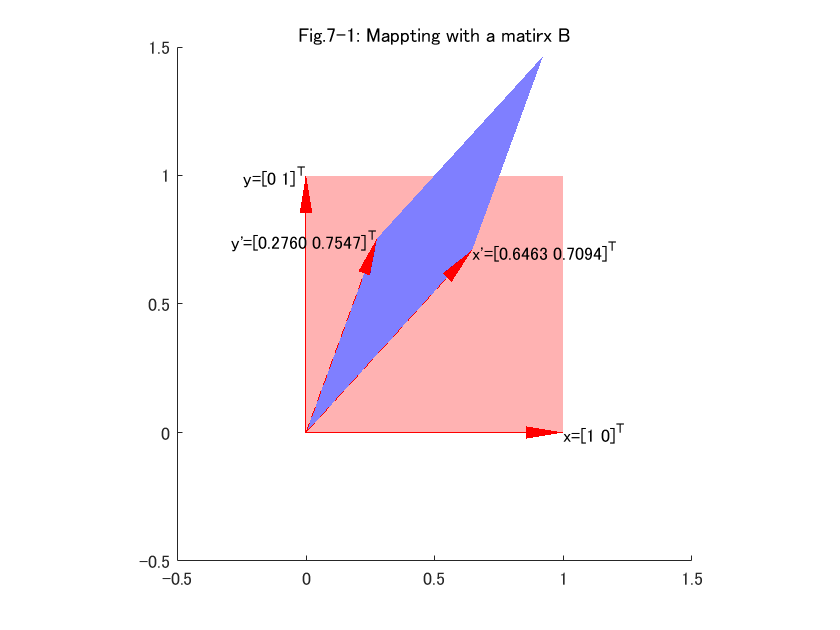

figure('Name','Fig.7-1: Mappting with a matirx B');
title('Fig.7-1: Mappting with a matirx B')
x = [1; 0];
y = [0; 1];
B = [0.6463 0.2760; 0.7094 0.7547];
xprime = B*x;
yprime = B*y;

patch([0 x(1) x(1)+y(1) y(1)],...
      [0 x(2) x(2)+y(2) y(2)],'red','FaceAlpha',0.3,'EdgeColor','none'); hold on;
patch([0 xprime(1) xprime(1)+yprime(1) yprime(1)],...
      [0 xprime(2) xprime(2)+yprime(2) yprime(2)],'blue','FaceAlpha',0.5,'EdgeColor','none');

axis([-0.5 1.5 -0.5 1.5]); axis square;
arrow3([0 0],x','r-'); text(x(1),x(2),'x=[1 0]^{T}','HorizontalAlignment','left');
arrow3([0 0],y','r-'); text(y(1),y(2),'y=[0 1]^{T}','HorizontalAlignment','right')
arrow3([0 0],xprime','r--');
str_xprime = sprintf('x''=[%0.4f %0.4f]^{T}',xprime(1),xprime(2));
text(xprime(1),xprime(2),str_xprime,'HorizontalAlignment','left');
arrow3([0 0],yprime','r--');
str_yprime = sprintf('y''=[%0.4f %0.4f]^{T}',yprime(1),yprime(2));
text(yprime(1),yprime(2),str_yprime,'HorizontalAlignment','right');

写像元のベクトル$x=\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack$および$y=\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack$はいずれも赤実線矢印で表しています．また，写像先のベクトル$x\prime =\left\lbrack \begin{array}{c}
0\ldotp 6463\\
0\ldotp 7094
\end{array}\right\rbrack$および$y\prime =\left\lbrack \begin{array}{c}
0\ldotp 2760\\
0\ldotp 7547
\end{array}\right\rbrack$はいずれも赤い点線矢印で表しています．ベクトル$x$および$y$がそれぞれ$x\prime$および$y\prime$に移っていることを確認してください．

#### 面積拡大率と行列式の幾何学的解釈

ここで，ベクトル$x$と$y$によって囲まれる領域（赤）と，$x\prime$と$y\prime$によって囲まれる領域（青）の面積を比較します．ベクトル$x$と$y$によって囲まれる領域の面積は1です．$x\prime$と$y\prime$によって囲まれる領域（青）の面積は，ふたつのベクトルの外積の長さとして求めることができます．

sprime = norm(cross([xprime;0],[yprime;0]))

sprime = 0.2920

$x\prime$と$y\prime$によって囲まれる領域（青）の面積は0.2920です．すなわち，行列$B$による写像で，面積が0.2920に縮小されたといえます．じつは，行列式は行列による写像の面積拡大縮小率を表します．実際に行列$B$の行列式を求めると，

det(B)

ans = 0.2920

となり，さきほどの外積の結果と一致します．

#### 行列による回転

回転を表す行列として，


$$\left\lbrack \begin{array}{cc}
\mathrm{cos}\theta  & -\mathrm{sin}\theta \\
\mathrm{sin}\theta  & \mathrm{con}\theta 
\end{array}\right\rbrack$$


があります．この行列によって，二次元ベクトル$x=\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack$および$y=\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack$はそれぞれ以下のように変換されます．


$$x\prime =\left\lbrack \begin{array}{c}
\mathrm{cos}\theta \\
\mathrm{sin}\theta 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\mathrm{cos}\theta  & -\mathrm{sin}\theta \\
\mathrm{sin}\theta  & \mathrm{con}\theta 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack$$



$$y\prime =\left\lbrack \begin{array}{c}
-\mathrm{sin}\theta \\
\mathrm{cos}\theta 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\mathrm{cos}\theta  & -\mathrm{sin}\theta \\
\mathrm{sin}\theta  & \mathrm{con}\theta 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack$$


$\theta =\pi /9$として，これらの関係を図示すると以下のようになります．

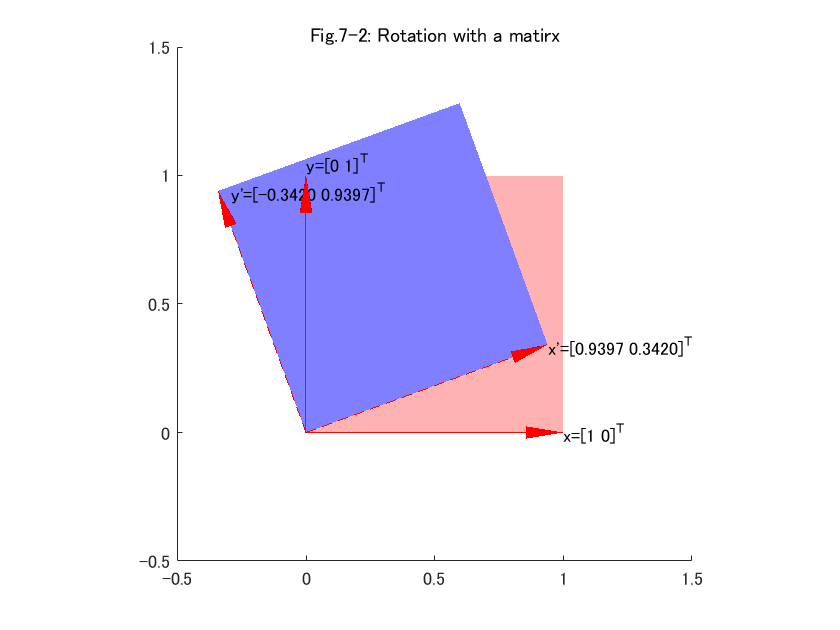

figure('Name','Fig.7-2: Rotation with a matirx');
title('Fig.7-2: Rotation with a matirx')
x = [1; 0];
y = [0; 1];
rad = pi/9;
Rot = [cos(rad) -sin(rad); sin(rad) cos(rad)];
xprime = Rot*x;
yprime = Rot*y;

patch([0 x(1) x(1)+y(1) y(1)],...
      [0 x(2) x(2)+y(2) y(2)],'red','FaceAlpha',0.3,'EdgeColor','none'); hold on;
patch([0 xprime(1) xprime(1)+yprime(1) yprime(1)],...
      [0 xprime(2) xprime(2)+yprime(2) yprime(2)],'blue','FaceAlpha',0.5,'EdgeColor','none');

axis([-0.5 1.5 -0.5 1.5]); axis square;
arrow3([0 0],x','r-'); text(x(1),x(2),'x=[1 0]^{T}','HorizontalAlignment','left');
arrow3([0 0],y','r-'); text(y(1),y(2),'y=[0 1]^{T}','HorizontalAlignment','left','VerticalAlignment','bottom')
arrow3([0 0],xprime','r--');
str_xprime = sprintf('x''=[%0.4f %0.4f]^{T}',xprime(1),xprime(2));
text(xprime(1),xprime(2),str_xprime,'HorizontalAlignment','left');
arrow3([0 0],yprime','r--');
str_yprime = sprintf('y''=[%0.4f %0.4f]^{T}',yprime(1),yprime(2));
text(yprime(1)+0.05,yprime(2),str_yprime,'HorizontalAlignment','left');

正方形が反時計回りに$\frac{\pi }{9}$だけ回転しています．行列式を計算してみると，

det(Rot)

ans = 1.0000

となり，拡大縮小はないことがわかります．

#### 行列による反転

さきほどの回転行列の列を入れ替えた行列，


$$\left\lbrack \begin{array}{cc}
-\mathrm{sin}\theta  & \mathrm{cos}\theta \\
\mathrm{cos}\theta  & \mathrm{sin}\theta 
\end{array}\right\rbrack$$


は，図を回転させた上に反転させます．この行列によって，二次元ベクトル$x=\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack$および$y=\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack$はそれぞれ以下のように変換されます．


$$x\prime =\left\lbrack \begin{array}{c}
-\mathrm{sin}\theta \\
\mathrm{cos}\theta 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\mathrm{cos}\theta  & -\mathrm{sin}\theta \\
\mathrm{sin}\theta  & \mathrm{con}\theta 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack$$



$$y\prime =\left\lbrack \begin{array}{c}
\mathrm{cos}\theta \\
\mathrm{sin}\theta 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\mathrm{cos}\theta  & -\mathrm{sin}\theta \\
\mathrm{sin}\theta  & \mathrm{con}\theta 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack$$


$\theta =\pi /9$として，これらの関係を図示すると以下のようになります．

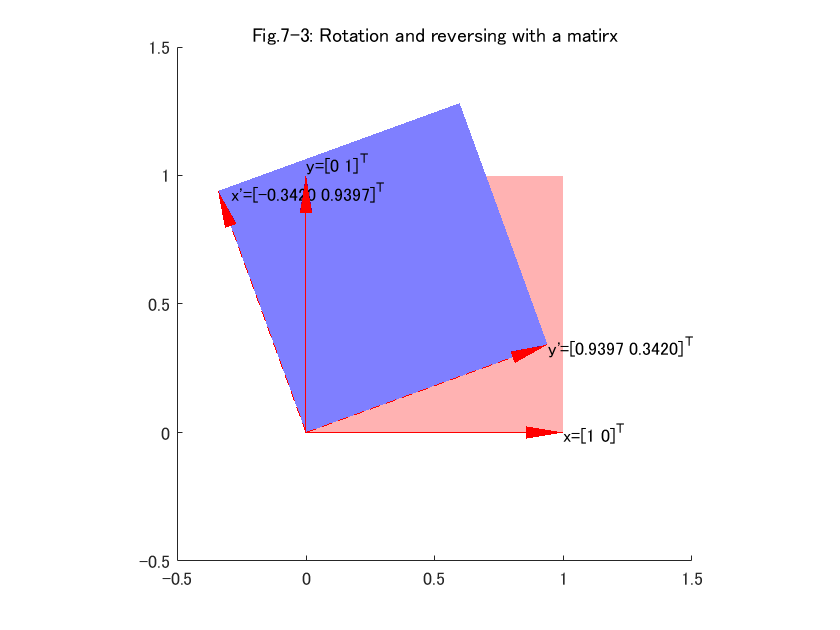

figure('Name','Fig.7-3: Rotation and reversing with a matirx');
title('Fig.7-3: Rotation and reversing with a matirx')
x = [1; 0];
y = [0; 1];
rad = pi/9;
RotRev = [-sin(rad) cos(rad); cos(rad) sin(rad)];
xprime = RotRev*x;
yprime = RotRev*y;

patch([0 x(1) x(1)+y(1) y(1)],...
      [0 x(2) x(2)+y(2) y(2)],'red','FaceAlpha',0.3,'EdgeColor','none'); hold on;
patch([0 xprime(1) xprime(1)+yprime(1) yprime(1)],...
      [0 xprime(2) xprime(2)+yprime(2) yprime(2)],'blue','FaceAlpha',0.5,'EdgeColor','none');

axis([-0.5 1.5 -0.5 1.5]); axis square;
arrow3([0 0],x','r-'); text(x(1),x(2),'x=[1 0]^{T}','HorizontalAlignment','left');
arrow3([0 0],y','r-'); text(y(1),y(2),'y=[0 1]^{T}','HorizontalAlignment','left','VerticalAlignment','bottom')
arrow3([0 0],xprime','r--');
str_xprime = sprintf('x''=[%0.4f %0.4f]^{T}',xprime(1),xprime(2));
text(xprime(1)+0.05,xprime(2),str_xprime,'HorizontalAlignment','left');
arrow3([0 0],yprime','r--');
str_yprime = sprintf('y''=[%0.4f %0.4f]^{T}',yprime(1),yprime(2));
text(yprime(1),yprime(2),str_yprime,'HorizontalAlignment','left');

先ほどの回転のみの場合と異なり，$x\prime$が左上に，$y\prime$が右下に位置していることに注意してください．なお，このときの行列式は

det(RotRev)

ans = -1.0000

となり，面積は変わらず，負の値になっています．一般に，行列式が負の値になることは，図形の反転を表します．

#### 直交行列と回転・反転

最後に直交行列$O$による写像を考えてみます．直交行列とは以下のような性質をもつ行列でした．

- 各列が互いに直行

- 各行が互いに直行

- 転置行列が逆行列に等しい

- 行列式が$1$または$-1$

前述したように，行列式が$\pm 1$のとき，その行列による写像は回転もしくは反転を表します．すなわち，直交行列による写像は回転もしくは反転したものになります．

## $u\prime =Q^T u$の幾何学的イメージ

それでは，$u\prime =Q^T u$を行列$Q^T$による写像として幾何学的に説明していきます．そのうえで，$S=\left(u\prime ,\mathit{Du}\prime \right)$のグラフは$S=\left(u,\mathit{Vu}\right)$を回転させたグラフであることをもう一度確認していきます．その後，座標の回転と座標軸の回転について解説していきます．

### 行列$Q^T$による写像

いま，適当な二次元ベクトル$x=\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack$に$2\times 2$の行列$Q^T$を左側から掛け，その結果を$x\prime =\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \prime \\
{\mathrm{x}}_2 \prime 
\end{array}\right\rbrack$とします．


$$x\prime =Q^T \textrm{x}$$


前述したように，行列$Q^T$は二次元ベクトル$x$をほかの二次元ベクトル$x\prime$に写像するものとみなすことができます．ここで行列$Q$は分散共分散行列$V$の固有値分解$V=\mathit{QD}Q^T$によって得られる行列です．前章で見たように，行列$Q$は直交行列になります．$Q$の行列式は

det(Q)

ans = 1.0000

となり，この行列による写像は回転を表すことがわかります．この行列$Q^T$による回転を上記のように図形で表してみます．

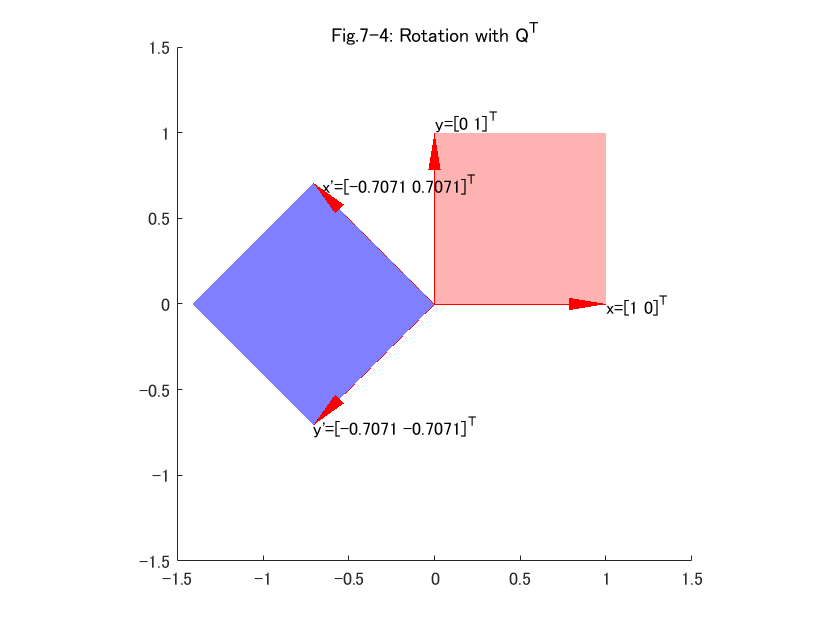

figure('Name','Fig.7-4: Rotation with Q^{T}');
title('Fig.7-4: Rotation with Q^{T}');
x = [1; 0];
y = [0; 1];
xprime = Q'*x;
yprime = Q'*y;

patch([0 x(1) x(1)+y(1) y(1)],...
      [0 x(2) x(2)+y(2) y(2)],'red','FaceAlpha',0.3,'EdgeColor','none'); hold on;
patch([0 xprime(1) xprime(1)+yprime(1) yprime(1)],...
      [0 xprime(2) xprime(2)+yprime(2) yprime(2)],'blue','FaceAlpha',0.5,'EdgeColor','none');

axis([-1.5 1.5 -1.5 1.5]); axis square;
arrow3([0 0],x','r-'); text(x(1),x(2),'x=[1 0]^{T}','HorizontalAlignment','left');
arrow3([0 0],y','r-'); text(y(1),y(2),'y=[0 1]^{T}','HorizontalAlignment','left','VerticalAlignment','bottom')
arrow3([0 0],xprime','r--');
str_xprime = sprintf('x''=[%0.4f %0.4f]^{T}',xprime(1),xprime(2));
text(xprime(1)+0.05,xprime(2),str_xprime,'HorizontalAlignment','left');
arrow3([0 0],yprime','r--');
str_yprime = sprintf('y''=[%0.4f %0.4f]^{T}',yprime(1),yprime(2));
text(yprime(1),yprime(2),str_yprime,'HorizontalAlignment','left');

赤色の領域はベクトル$x=\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack$と$y=\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack$に囲まれる領域を表します．青色の領域は$x\prime =Q^T x$および$y\prime =Q^T y$に囲まれる領域です．行列$Q^T$によって領域は反時計回りに135度ほど回転している様子が読み取れます．

### 行列$Q^T$によるデータ行列$X$の回転

上記の例ではベクトル$x=\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack$および$y=\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack$を用いて，行列$Q^T$による写像が回転することを確かめました．しかし，行列$Q^T$による写像はベクトル$x$，$y$に限らず，任意の二次元ベクトルを回転させることができます．ここでは，行列$Q^T$によるデータ行列$X$の回転をグラフにして，元のデータ行列との違いを確かめてみます．

データ行列$X$は各変数（「健康」および「芸術」）を行に，各観測を列にした２行３２９行の行列です．

X

X =    -0.9459    0.4689   -0.5660    0.2445    0.6653   -0.5441   -0.5630   -0.2201   -0.7515   -0.5152    0.8367   -0.5830   -0.6039   -0.3646    1.3183   -0.5860   -0.3517    0.0182   -0.5790    2.0032   -0.5471    0.6104    0.0172   -0.4025   -0.7634    2.3691   -0.4045   -0.8412   -0.2849   -0.5680   -0.3238   -0.9429   -0.6139    1.4708   -0.7046   -0.7425   -0.1782    0.5047   -0.3806   -0.4534   -0.3696   -0.7305    4.1029   -0.2231   -0.8502   -0.7455   -0.8731    1.3602   -0.2101   -0.2689
   -0.4642    0.5198   -0.6277    0.3240    0.2898   -0.6068   -0.1762   -0.3584   -0.6236   -0.4127    0.5345   -0.1734   -0.5861   -0.6423    0.9496   -0.6210   -0.4276   -0.3791    0.0851    0.9496   -0.5450   -0.4532    0.1521    0.4748   -0.4155    1.4297   -0.2490    0.2340   -0.6025   -0.2921   -0.4021   -0.3983   -0.6617    1.3255   -0.5111   -0.5325   -0.3343    0.1739   -0.4179   -0.2152   -0.3621   -0.1650    3.8539    0.1103   -0.6456   -0.3543   -0.5964    1.1238   -0.5680   -0

各観測（列）を二次元ベクトルとして，それぞれの二次元ベクトルが行列$Q^T$の写像によってどのように回転するかを見ていきます．たとえば，データ行列$X$の一列目の写像は

Q'*X(:,1)

ans =     0.9971
   -0.3406


のように求めることができます．同様に二列目は

Q'*X(:,2)

ans =    -0.6991
   -0.0360


となります．すべての列にたいする写像は以下のようにして求めることができます．


$$X\prime =Q^T X$$


ここで，行列$X\prime$は２行３２９列の行列で，各列はデータ行列$X$の各列に対応します．実際に計算してみると，

Xprime = Q'*X

Xprime =     0.9971   -0.6991    0.8441   -0.4020   -0.6753    0.8138    0.5227    0.4091    0.9723    0.6561   -0.9696    0.5348    0.8415    0.7120   -1.6036    0.8535    0.5510    0.2552    0.3492   -2.0879    0.7722   -0.1112   -0.1197   -0.0511    0.8336   -2.6862    0.4621    0.4294    0.6275    0.6082    0.5133    0.9484    0.9020   -1.9773    0.8597    0.9015    0.3624   -0.4798    0.5646    0.4727    0.5174    0.6332   -5.6264    0.0797    1.0577    0.7777    1.0391   -1.7565    0.5502    0.3653
   -0.3406   -0.0360    0.0436   -0.0562    0.2655    0.0443   -0.2736    0.0978   -0.0904   -0.0725    0.2138   -0.2896   -0.0126    0.1964    0.2607    0.0248    0.0537    0.2809   -0.4696    0.7451   -0.0015    0.7521   -0.0954   -0.6204   -0.2460    0.6643   -0.1100   -0.7603    0.2246   -0.1951    0.0554   -0.3851    0.0338    0.1028   -0.1368   -0.1485    0.1104    0.2340    0.0264   -0.1684   -0.0053   -0.3999    0.1761   -0.2357   -0.1447   -0.2766   -0.1956    0.1671    0.2531

となります．データ行列$X$と写像後の行列$X\prime$のグラフを以下に示します．

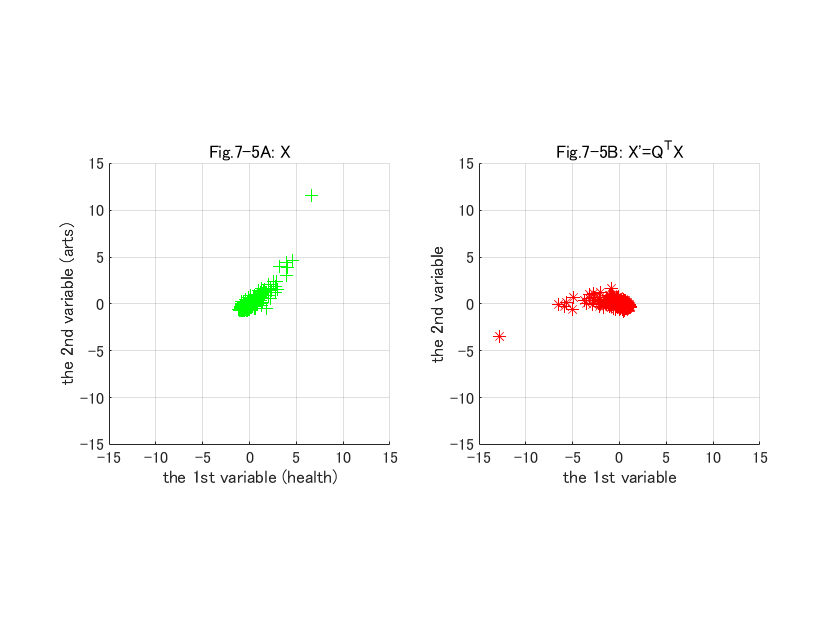

figure('Name','Fig.7-5: X vs. X''');
subplot(1,2,1);
scatter(X(1,:),X(2,:),'g+');
title('Fig.7-5A: X');
axis([-15 15 -15 15]); axis square; grid on;
xlabel('the 1st variable (health)'); ylabel('the 2nd variable (arts)');

subplot(1,2,2);
scatter(Xprime(1,:),Xprime(2,:),'r*');
title('Fig.7-5B: X''=Q^{T}X');
axis([-15 15 -15 15]); axis square; grid on;
xlabel('the 1st variable'); ylabel('the 2nd variable');

左図がデータ行列$X$の各行（変数）を横軸（「健康」）と縦軸（「芸術」）にした散布図です．右図が$X\prime =Q^T X$によって回転を施された行列$X\prime$の散布図です．一行目を縦軸，二行目を横軸にしています．データ行列$X$も行列$Q^T$による写像で，反時計回りに１３５度ほど回転している様子が見て取れます．なお，右図において，縦軸と横軸は「健康」や「芸術」といった単独の指標を表していないことに注意してください（詳細は後述します）．

#### 主成分スコアと$X\prime$

ここで，pca()関数の二つ目の出力引数である主成分スコアと行列$X\prime \left(=Q^T X\right)$の関係を見ておきます．データ行列$X$の主成分スコアは

[coefs,scores] = pca(X','Algorithm','eig');
scores' % presents transposed scores 

ans =    -0.9971    0.6991   -0.8441    0.4020    0.6753   -0.8138   -0.5227   -0.4091   -0.9723   -0.6561    0.9696   -0.5348   -0.8415   -0.7120    1.6036   -0.8535   -0.5510   -0.2552   -0.3492    2.0879   -0.7722    0.1112    0.1197    0.0511   -0.8336    2.6862   -0.4621   -0.4294   -0.6275   -0.6082   -0.5133   -0.9484   -0.9020    1.9773   -0.8597   -0.9015   -0.3624    0.4798   -0.5646   -0.4727   -0.5174   -0.6332    5.6264   -0.0797   -1.0577   -0.7777   -1.0391    1.7565   -0.5502   -0.3653
    0.3406    0.0360   -0.0436    0.0562   -0.2655   -0.0443    0.2736   -0.0978    0.0904    0.0725   -0.2138    0.2896    0.0126   -0.1964   -0.2607   -0.0248   -0.0537   -0.2809    0.4696   -0.7451    0.0015   -0.7521    0.0954    0.6204    0.2460   -0.6643    0.1100    0.7603   -0.2246    0.1951   -0.0554    0.3851   -0.0338   -0.1028    0.1368    0.1485   -0.1104   -0.2340   -0.0264    0.1684    0.0053    0.3999   -0.1761    0.2357    0.1447    0.2766    0.1956   -0.1671   -0.2531   

となります．比較のために，$X\prime$の内容も再掲すると

Xprime

Xprime =     0.9971   -0.6991    0.8441   -0.4020   -0.6753    0.8138    0.5227    0.4091    0.9723    0.6561   -0.9696    0.5348    0.8415    0.7120   -1.6036    0.8535    0.5510    0.2552    0.3492   -2.0879    0.7722   -0.1112   -0.1197   -0.0511    0.8336   -2.6862    0.4621    0.4294    0.6275    0.6082    0.5133    0.9484    0.9020   -1.9773    0.8597    0.9015    0.3624   -0.4798    0.5646    0.4727    0.5174    0.6332   -5.6264    0.0797    1.0577    0.7777    1.0391   -1.7565    0.5502    0.3653
   -0.3406   -0.0360    0.0436   -0.0562    0.2655    0.0443   -0.2736    0.0978   -0.0904   -0.0725    0.2138   -0.2896   -0.0126    0.1964    0.2607    0.0248    0.0537    0.2809   -0.4696    0.7451   -0.0015    0.7521   -0.0954   -0.6204   -0.2460    0.6643   -0.1100   -0.7603    0.2246   -0.1951    0.0554   -0.3851    0.0338    0.1028   -0.1368   -0.1485    0.1104    0.2340    0.0264   -0.1684   -0.0053   -0.3999    0.1761   -0.2357   -0.1447   -0.2766   -0.1956    0.1671    0.2531

です．主成分スコアと$X\prime$は符号が反転した関係にあります．両者をグラフにして比較すると，

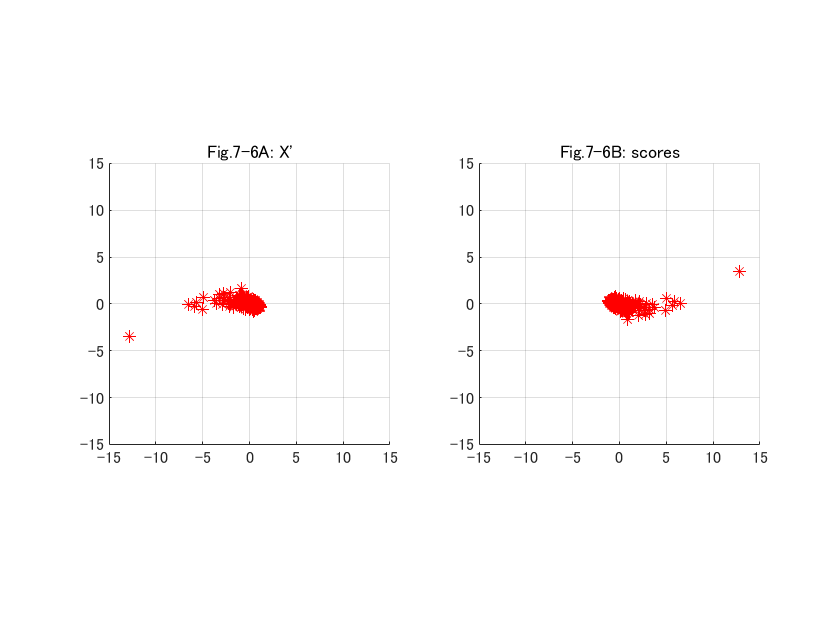

figure('Name','Fig.7-6: X'' vs. scores ');
subplot(1,2,1);
title('Fig.7-6A: X'''); hold on;
scatter(Xprime(1,:),Xprime(2,:),'r*');
grid on; axis([-15 15 -15 15]); axis square;

subplot(1,2,2);
title('Fig.7-6B: scores'); hold on;
scatter(scores(:,1),scores(:,2),'r*');
grid on; axis([-15 15 -15 15]); axis square;

左図が$X\prime$の散布図で，右図がscoresの散布図です．両社は互いに１８０度回転した図形になっています．これは，行列$Q$と主成分係数coefsの違いによります．いかにそれぞれの値を表示すると，

Q

Q =    -0.7071    0.7071
   -0.7071   -0.7071


coefs

coefs =     0.7071   -0.7071
    0.7071    0.7071


となります．両社は互いに符号が反転しています．これは，分散共分散行列$V$の固有ベクトルが一意に決まらないためです．前章でみたように，分散共分散行列$V$のひとつの固有値に対する固有ベクトルは符号（向き）が異なる二つのベクトルが求まります．上記の例では，eig()関数とpca()関数はそれぞれ反対方向の固有ベクトルを採用してしまったためこのような違いが起こったものと思われます．

一般に，PCAの主成分スコアと$X\prime =Q^T X$は同じものと考えることができます．すなわち，データ行列$X$を行列$Q^T$によって回転させたものが主成分スコアとなります．ただし行列$Q$はデータ行列の分散共分散行列$V$の固有値分解$V=\mathit{QD}Q^T$によって得られる行列です．

#### 行列$Q$による写像

上記のように，$x\prime =Q^T x$という演算はベクトル$x$をベクトル$x\prime$に関連付ける（移動させる）意味を持っています．この関係を，


$$x=\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack \Longrightarrow^{Q^T } x\prime =\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \prime \\
{\mathrm{x}}_2 \prime 
\end{array}\right\rbrack$$


と表すことにします．また，対称行列の固有値ベクトルは互いに直交することから，$Q^{-1} =Q^T$が成り立ちます．このとき，$x\prime =Q^T x$の両辺に左から$Q$をかけると，


$$x={\mathit{Qx}}^{\prime }$$


となります．前述の表記方法を用いると，この関係は，


$$x\prime =\left\lbrack \begin{array}{c}
x_1 \prime \\
x_2 \prime 
\end{array}\right\rbrack \Longrightarrow^Q$$

$$x=\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack$$


となります．すなわち，行列$Q$による写像は，もとの二次元ベクトルに戻す操作として解釈することができます．

## 行列$X\prime$における正射影ベクトルの長さの分散

前章では，分散共分散行列$V$の固有値分解$V=\mathit{QD}Q^T$を用いて，二次形式$S=\left(u,\mathit{Vu}\right)$を標準形$S=\left(u\prime ,\mathit{Du}\prime \right)$にし，$S=\left(u\prime ,\mathit{Du}\prime \right)$のグラフが$S=\left(u,\mathit{Vu}\right)$のグラフを回転させたものであると指摘しました（ただし，$u\prime =Q^T$）．その結果，$S=\left(u\prime ,\mathit{Du}\prime \right)$のグラフは各座標軸上で分散がもっともよく表されるようになっていることを確認しました．ここでは，$X\prime =Q^T X$の任意の方向における分散を求めることで，そのことを確認します．

### 行列$X\prime$における正射影ベクトルの長さの分散

データ行列$X$の時と同様，任意の単位ベクトル$u\prime =\left\lbrack \begin{array}{c}
{\mathrm{u}}_1 \prime \\
{\mathrm{u}}_2 \prime 
\end{array}\right\rbrack$で示される方向における分散を求めます．

まず，行列$X\prime$の分散共分散行列は


$$V\prime =\frac{1}{\mathrm{N}}X\prime {X\prime }^T$$


として求めることができます．ただし$\mathrm{N}$は$X\prime$の列数です（$\mathrm{N}=329$）．上式に$X\prime =Q^T X$を代入すると，


$$V\prime =\frac{1}{\mathrm{N}}\left(Q^T X\right){\left(Q^T X\right)}^T =\frac{1}{\mathrm{N}}Q^T XX^T Q$$


となります．さらに，$V=\frac{1}{\mathrm{N}}XX^T$を代入すると


$$V\prime =Q^T \mathit{VQ}$$


となります．つづいて，分散共分散行列$V\prime$の固有値分解を行います．ここで，$V=\mathit{QD}Q^T$を用いると，上式は


$$V\prime =Q^T \left(\mathit{QD}Q^T \right)Q=D$$


となります．ここで行列$Q$が直交行列であり，$Q^T Q=QQ^T =I$となることを利用しました．上記の結果は，分散共分散行列$V\prime$の固有値分解は


$$V\prime =D$$


となることを表しています．ここで，行列$D$は分散共分散行列$V$の固有値を対角成分とする対角行列です．したがって，行列$X\prime$の任意の方向における分散は


$$S=\left(u\prime ,\mathit{Du}\prime \right)$$


と表されます．いま，$D=\left\lbrack \begin{array}{cc}
1\ldotp 8601 & 0\\
0 & 0\ldotp 1338
\end{array}\right\rbrack$とすると，$S=\left(u\prime ,\mathit{Du}\prime \right)$の成分表記は


$$S=1\ldotp 8601{u_1 \prime }^2 +0\ldotp 1338{u_2 \prime }^2$$


となります．ただし，$\left\|u\prime \right\|=\sqrt{{u_1 \prime }^2 +{u_2 \prime }^2 }=1$です．

ここで，


$$g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=1\ldotp 8601{{\mathrm{x}}_1 \prime }^2 +0\ldotp 1338{{\mathrm{x}}_1 \prime }^2$$


として，${\mathrm{x}}_3 \prime =g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)$のグラフを確認してみます．

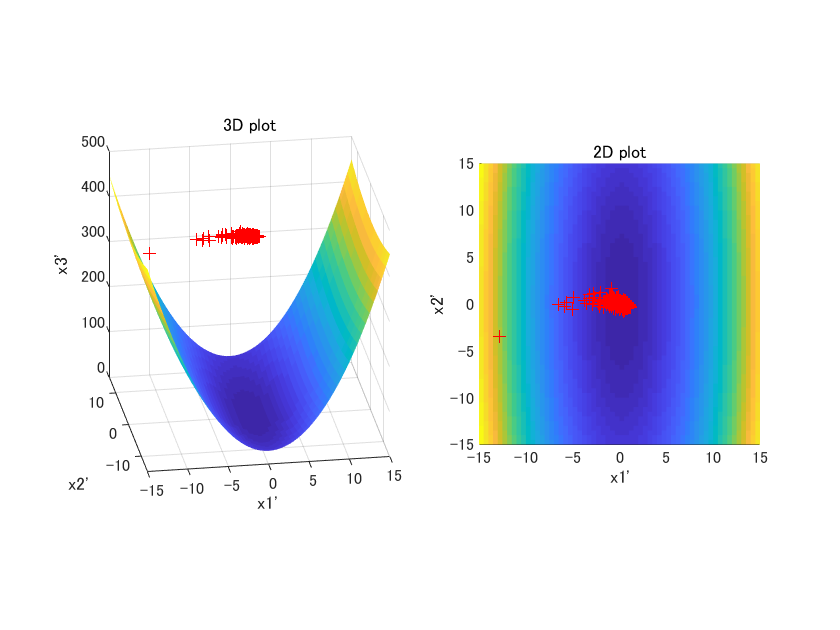

figure('Name','Fig.7-7: Visualization of x3''=g(x1'',x2'')');
[x1grid,x2grid] = meshgrid(-15:0.5:15, -15:0.5:15);
x3 = D(1,1)*x1grid.^2 + D(2,2)*x2grid.^2; 
subplot(1,2,1); s = surf(x1grid,x2grid,x3); view([-9 23]);
s.EdgeColor = 'none'; axis square;
title('3D plot'); xlabel('x1'''); ylabel('x2'''); zlabel('x3''');
hold on; scatter3(Xprime(1,:),Xprime(2,:),ones(size(Xprime(1,:)))*400,'r+');
axis([-15 15 -15 15 0 500]);
subplot(1,2,2); s = surf(x1grid,x2grid,x3); view([0 90]);
s.EdgeColor = 'none'; axis square;
title('2D plot'); xlabel('x1'''); ylabel('x2'''); zlabel('x3''');
hold on; scatter3(Xprime(1,:),Xprime(2,:),ones(size(Xprime(1,:)))*400,'r+');
axis([-15 15 -15 15 0 500]);

左図は三次元空間上に関数${\mathrm{x}}_3 \prime =g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)$をプロットしたものです．右図は，${{\mathrm{x}}_1 }^{\prime } {{\mathrm{x}}_2 }^{\prime }$平面上で${{\mathrm{x}}_3 }^{\prime }$の大きさを色で表現したカラーマップです．いずれも，$X\prime$の各列を赤い十字でプロットしています．関数${\mathrm{x}}_3 \prime =g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)$の勾配は${\mathrm{x}}_1 \prime$軸上でもっとも大きくなっているのが見て取れます．

最後に，$S=\left(u\prime ,\mathit{Du}\prime \right)$をグラフにします．このグラフは，


$$\begin{array}{l}
{\mathrm{x}}_3 \prime =g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)\\
{{\mathrm{x}}_1 \prime }^2 +{{\mathrm{x}}_2 \prime }^2 =1
\end{array}$$


を同時に満たす点です．

figure('Name','Fig.7-8: Visualazation of S=(u'',Du'')');

t1_upper = linspace(0,pi,100)';
x1_upper = cos(t1_upper);
x2_upper = sin(t1_upper);
x3_upper = [x1_upper x2_upper]*D*[x1_upper x2_upper]';
x3_upper = diag(x3_upper);
plot3(x1_upper,x2_upper,x3_upper,'r-'); hold on;

t1_lower = linspace(pi,2*pi,100)';
x1_lower = cos(t1_lower);
x2_lower = sin(t1_lower);
x3_lower = [x1_lower x2_lower]*D*[x1_lower x2_lower]';
x3_lower = diag(x3_lower);
plot3(x1_lower,x2_lower,x3_lower,'r-'); hold on;

t = linspace(0,2*pi,100);
plot3(cos(t),sin(t),zeros(size(t)),'k--');

[x3_max, max_ind] = max(x3_lower);
x1_max = x1_upper(max_ind);
x2_max = x2_upper(max_ind);
arrow3([0 0 0],[x1_max,x2_max,0],'r--');

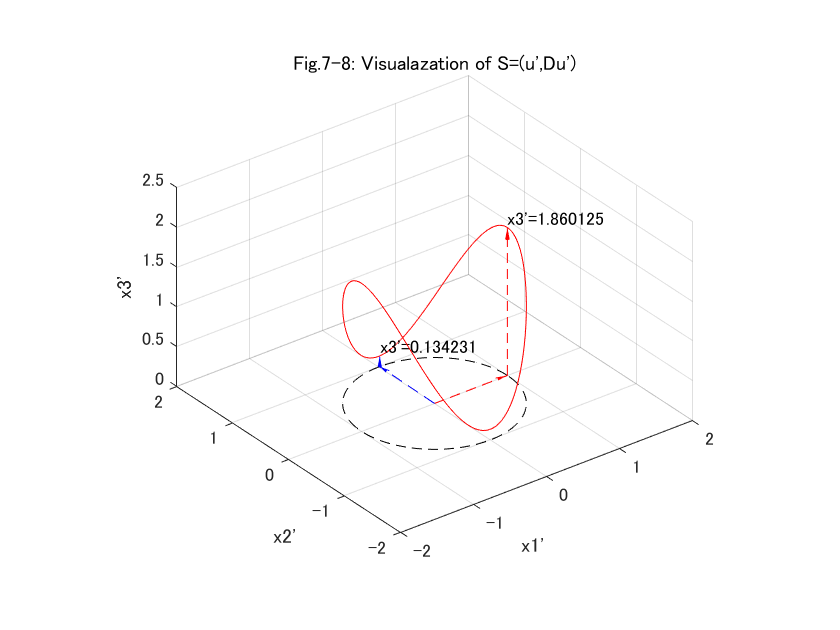

arrow3([x1_max,x2_max,0],[x1_max,x2_max,x3_max],'r--');
str_max = sprintf('x3''=%f',x3_max); text(x1_max,x2_max,x3_max,str_max,'VerticalAlignment','bottom');

[x3_min, min_ind] = min(x3_lower);
x1_min = x1_upper(min_ind);
x2_min = x2_upper(min_ind);
arrow3([0 0 0],[x1_min,x2_min,0],'b--');
arrow3([x1_min,x2_min,0],[x1_min,x2_min,x3_min],'b--');
str_min = sprintf('x3''=%f',x3_min); text(x1_min,x2_min,x3_min,str_min,'VerticalAlignment','bottom');

title('Fig.7-8: Visualazation of S=(u'',Du'')'); hold on;
xlim([-2 2]); ylim([-2 2]); zlim([0 2.5]); grid on;
xlabel('x1'''); ylabel('x2'''); zlabel('x3''');

$X\prime =Q^T X$の分散を直接求めた場合も，${\mathrm{x}}_1 \prime$軸上（${\mathrm{x}}_1 \prime =1$，${\mathrm{x}}_2 \prime =0$）で分散は最大（${\mathrm{x}}_3 \prime =1\ldotp 86125$）となり，それと直交する方向すなわち${\mathrm{x}}_2 \prime$軸上（${\mathrm{x}}_1 \prime =0$，${\mathrm{x}}_2 \prime =1$）で分散は最小（${\mathrm{x}}_3 \prime =0\ldotp 134231$）となることがわかります．

## これまでのまとめ

前章では，正射影ベクトルの長さの分散$S=\left(u,\mathit{Vu}\right)$を分散共分散行列$V$の固有値分解$V=\mathit{QD}Q^T$を用いて式変形して，$S=\left(u\prime ,\mathit{Du}\prime \right)$という式を導出しました（ただし，$u\prime =Q^T u$）．そして，$S=\left(u\prime ,\mathit{Du}\prime \right)$のグラフは$S=\left(u,\mathit{Vu}\right)$を回転させたグラフであることを解説しました．

本章では，この回転について詳しく解説しました．まず，一般の行列による写像を解説し，行列による写像は図形の拡大縮小や回転，反転として図形的に解釈することを紹介しました．その際，行列式の絶対値が拡大縮小率を表し，その符号が反転・非反転を表すことを紹介しました．つづいて，分散共分散行列$V$の固有値分解$V=\mathit{QD}Q^T$で得られる行列$Q$を用いた$u\prime =Q^T u$という写像の幾何学的なイメージを解説しました．行列$Q$は直交行列となるため，その写像は回転や反転を表します．さらに，PCAにおける主成分スコアは行列$Q^T$によるデータ行列$X$の回転，すなわち$X\prime =Q^T X$であることを説明しました．最後に，$S=\left(u\prime ,\mathit{Du}\prime \right)$を$X\prime =Q^T X$から直接求めて，データの回転と，回転されたデータの任意の方向における分散の関係を確認しました．

次章では，行列による写像について，「座標の変換」と「座標軸の変換」というふたつの異なる見方を紹介します．